# Homework 3

**Sebastian Aguilera Novoa**

## **1. Limite on an Optimization Problem**

Given a matrix $J \in \mathbb{R}^{m\times n}$ and a matrix $Q \in \mathbb{R}^{n\times n}$ symmetric defined positive $Q \succ 0$, a vector of measures $\eta \in \mathbb{R}$ and a point $\overline{x}\in \mathbb{R}$, calculate the limite

## 2. Linear fitting in $L_2$

Suppose there is a set of $N$ noisy measures $(x_i,y_i)\in \mathbb{R}^2$ that we want to fit a line $y=ax+b$. The previous can be expressed as the following optimization problem

Like was discussed in class, the optimal solution to the previous problem can be calculated explicity by solving the normal Gauss equations

### 1.

Generate the problem data. Take $N=30$ points in the interval $[0,5]$ and generate the true outputs $y_i=3x_i+4$. Add gaussian noise with zero mean and standard deviation 1 to get the noisy data and plot them. *Advice:* check the commands `linspace` and `randn`. If you want a "random" reproducible serie, use `rng`.

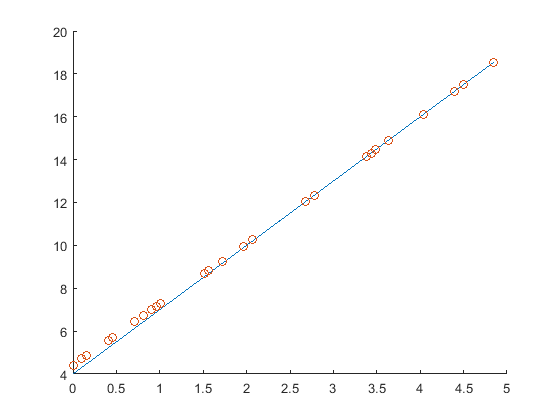

N = 30;
rng(1)
xrand = [];
x = linspace(0,5,100);  
xi = randi(100,1,N);
for i=xi
   xrand = [xrand x(i)];
end

y = 3*xrand+4;
ynoise = y + (1/sqrt(2*pi)).*exp(-xrand.^2/2);
clf;
hold on;
plot(xrand,y)
plot(xrand,ynoise, 'o')
hold off;

%ynoisy = awgn(y,7);

'awgn' requires Communications Toolbox.

%y = gaussmf(x,[1 0]);



### 2.

Write the matrix $J$. Calculate the coefficients$a, \;b$using the last equation and plot the measures and line getted in the same plane.

### 3.

Introduce 3 atypical data in the measures $y$ and plot the new fitted line in the same plane.

The measures $y$ (with and without the atypical data) and the matrix $J$are necessary to the following point.

## 3.Linear Fitting in $L_1$

Now we are interesting to fit a line to the same measure set, but now using the following objective function

The objective function is not differentiable, then we are going to use width variables to get the following equivalent linear programming problem 

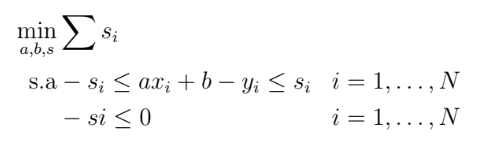

### 1.

In order to solve the previous linear programming problem use the MATLAB command `linprog`, to do this is necessary to write the problem as follows

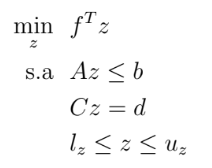

Write the matrix $A$ and the vectors $f,b$. Organize he variables as $z=[a,b, s_1,\dots ,s_N]$ Use the matrix $J$ from the previous exercise to define $A$.

### 2.

Solve the problem using the $y$ measures from the previous exercise (without the atypical data) and plot the results over the $L_2$ results. Which norm has a better result?

### 3.

Solve the problem with CasADi and compare the results.

## 4. Integral Equation

Consider the following integral equation

### a)

Find the exact solution (*Advice: *Interprete the operator $A:L^2(0,1)\to L^2(0,1)$ as the Laplace transform).

### b)

Use the trapezio rule with an integer step $h=1/n$ and $s=ih$ i$i=1,\dots,n$ to get a linear system of equations.

### c)

Find the solution to the linear system for $n=4,8,16,32$ and plot them. Point out the number condition of each linear system using the command `cond` on MATLAB.

### d)

Solve the integral equation using the regularization method for each of the following parameters: i) $n=100, \; \alpha=0.2$, i) $n=100, \; \alpha=0.1$, and i) $n=100, \; \alpha=10^{-3}$. Plot the solutions.